%% 1) Load three candidates MAT files
S1 = load('candidates_apt1.mat');    % => S1.candidates
S2 = load('candidates_apt1p5.mat');  % => S2.candidates
S3 = load('candidates_apt2.mat');    % => S3.candidates
S4 = load('candidates_apt2p5.mat');  % => S4.candidates
S5 = load('candidates_apt3.mat');    % => S5.candidates
S6 = load('candidates_apt3p5.mat');  % => S6.candidates
S7 = load('candidates_apt4.mat');    % => S7.candidates

% Extract positions (x,y) for each file
pos1 = [S1.candidates.pos_x(:), S1.candidates.pos_y(:)];
pos2 = [S2.candidates.pos_x(:), S2.candidates.pos_y(:)];
pos3 = [S3.candidates.pos_x(:), S3.candidates.pos_y(:)];
pos4 = [S4.candidates.pos_x(:), S4.candidates.pos_y(:)];
pos5 = [S5.candidates.pos_x(:), S5.candidates.pos_y(:)];
pos6 = [S6.candidates.pos_x(:), S6.candidates.pos_y(:)];
pos7 = [S7.candidates.pos_x(:), S7.candidates.pos_y(:)];

% Extract raw contrast arrays
ctr1 = S1.candidates.iscat.ctr(:);
ctr2 = S2.candidates.iscat.ctr(:);
ctr3 = S3.candidates.iscat.ctr(:);
ctr4 = S4.candidates.iscat.ctr(:);
ctr5 = S5.candidates.iscat.ctr(:);
ctr6 = S6.candidates.iscat.ctr(:);
ctr7 = S7.candidates.iscat.ctr(:);

% Also create third-root contrasts for S2 and S3
ctr2_thirdroot = ctr2.^(1/3);
ctr3_thirdroot = ctr3.^(1/3);
ctr4_thirdroot = ctr4.^(1/3);
ctr5_thirdroot = ctr5.^(1/3);
ctr6_thirdroot = ctr6.^(1/3);
ctr7_thirdroot = ctr7.^(1/3);

% For reporting
fprintf('Sizes:\n pos1: %dx%d, pos2: %dx%d, pos3: %dx%d, pos4: %dx%d\n',... % pos5: %dx%d, pos6: %dx%d, pos7 %dx%d\n',...
    size(pos1,1), size(pos1,2), ...
    size(pos2,1), size(pos2,2), ...
    size(pos3,1), size(pos3,2), ...
    size(pos4,1), size(pos4,2));

Sizes:
 pos1: 42083x2, pos2: 44607x2, pos3: 45282x2, pos4: 45818x2


    size(pos5,1), size(pos5,2), ...
    size(pos6,1), size(pos6,2), ...
    size(pos7,1), size(pos7,2));

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.


%% 2) Filter S1 by a desired third-root contrast range
valMin = 0.16;
valMax = 0.5;

% Compute 3rd-root of S1's contrast
ctr1_thirdroot = ctr1.^(1/3);

% Find only those S1 spots in the desired 3rd-root range
idx1 = (ctr1_thirdroot >= valMin) & (ctr1_thirdroot <= valMax);

% Subset S1 positions and S1 third-root contrast to just those
pos1_filt          = pos1(idx1, :);
ctr1_thirdroot_filt = ctr1_thirdroot(idx1);
N1_filt            = size(pos1_filt,1);

fprintf('After filtering S1 by 3rd-root in [%.2f, %.2f], we have %d spots.\n',...
    valMin, valMax, N1_filt);

After filtering S1 by 3rd-root in [0.16, 0.50], we have 286 spots.



%% 3) Build KD-trees for S2,S3,S4,S5,S6 and S7
% (We'll match S1's filtered spots to these.)
kdtree2 = KDTreeSearcher(pos2);
kdtree3 = KDTreeSearcher(pos3);
kdtree4 = KDTreeSearcher(pos4);
kdtree5 = KDTreeSearcher(pos5);
kdtree6 = KDTreeSearcher(pos6);
kdtree7 = KDTreeSearcher(pos7);

%% 4) For each filtered S1 spot, find a match in S2 and S3 within tolerance
tol =2.0;  % e.g. 4 pixels

neighborsPos2 = rangesearch(kdtree2, pos1_filt, tol);
neighborsPos3 = rangesearch(kdtree3, pos1_filt, tol);
neighborsPos4 = rangesearch(kdtree4, pos1_filt, tol);
neighborsPos5 = rangesearch(kdtree5, pos1_filt, tol);
neighborsPos6 = rangesearch(kdtree6, pos1_filt, tol);
neighborsPos7 = rangesearch(kdtree7, pos1_filt, tol);

% We'll store the matched 3rd-root contrast across the 3 files 
% matchedTransformed(i,1) = S1 3rd-root contrast
% matchedTransformed(i,2) = S2 3rd-root contrast
% matchedTransformed(i,3) = S3 3rd-root contrast
% On suppose que tu compares S1 avec S2 à S7
matchedTransformed = nan(N1_filt, 4);  % Colonne 1 = S1, 2 à 7 = S2 à S7
matchedTransformed(:,1) = ctr1_thirdroot_filt;  % S1 contrastes ³√ filtrés

for i = 1:N1_filt
    % --- S2 ---
    idxList2 = neighborsPos2{i};
    if numel(idxList2) == 1
        matchedTransformed(i,2) = ctr2_thirdroot(idxList2);
    elseif numel(idxList2) > 1
        distList2 = sqrt(sum((pos2(idxList2,:) - pos1_filt(i,:)).^2, 2));
        [~, minIdx] = min(distList2);
        matchedTransformed(i,2) = ctr2_thirdroot(idxList2(minIdx));
    end

    % --- S3 ---
    idxList3 = neighborsPos3{i};
    if numel(idxList3) == 1
        matchedTransformed(i,3) = ctr3_thirdroot(idxList3);
    elseif numel(idxList3) > 1
        distList3 = sqrt(sum((pos3(idxList3,:) - pos1_filt(i,:)).^2, 2));
        [~, minIdx] = min(distList3);
        matchedTransformed(i,3) = ctr3_thirdroot(idxList3(minIdx));
    end

    % --- S4 ---
    idxList4 = neighborsPos4{i};
    if numel(idxList4) == 1
        matchedTransformed(i,4) = ctr4_thirdroot(idxList4);
    elseif numel(idxList4) > 1
        distList4 = sqrt(sum((pos4(idxList4,:) - pos1_filt(i,:)).^2, 2));
        [~, minIdx] = min(distList4);
        matchedTransformed(i,4) = ctr4_thirdroot(idxList4(minIdx));
    end

    % --- S5 ---
    idxList5 = neighborsPos5{i};
    if numel(idxList5) == 1
       matchedTransformed(i,5) = ctr5_thirdroot(idxList5);
    elseif numel(idxList5) > 1
       distList5 = sqrt(sum((pos5(idxList5,:) - pos1_filt(i,:)).^2, 2));
       [~, minIdx] = min(distList5);
       matchedTransformed(i,5) = ctr5_thirdroot(idxList5(minIdx));
    end

    % --- S6 ---
    idxList6 = neighborsPos6{i};
    if numel(idxList6) == 1
       matchedTransformed(i,6) = ctr6_thirdroot(idxList6);
    elseif numel(idxList6) > 1
       distList6 = sqrt(sum((pos6(idxList6,:) - pos1_filt(i,:)).^2, 2));
       [~, minIdx] = min(distList6);
       matchedTransformed(i,6) = ctr6_thirdroot(idxList6(minIdx));
    end

    % --- S7 ---
   idxList7 = neighborsPos7{i};
   if numel(idxList7) == 1
       matchedTransformed(i,7) = ctr7_thirdroot(idxList7);
   elseif numel(idxList7) > 1
       distList7 = sqrt(sum((pos7(idxList7,:) - pos1_filt(i,:)).^2, 2));
       [~, minIdx] = min(distList7);
       matchedTransformed(i,7) = ctr7_thirdroot(idxList7(minIdx));
   end
end

% Garder seulement les lignes où tous les spots sont appariés (aucun NaN)
validRows = ~any(isnan(matchedTransformed), 2);
matchedTransformedValid = matchedTransformed(validRows, :);
numValid = sum(validRows);

fprintf('Found %d filtered S1 spots that matched in S2 to S4.\n', numValid);

Found 50 filtered S1 spots that matched in S2 to S4.


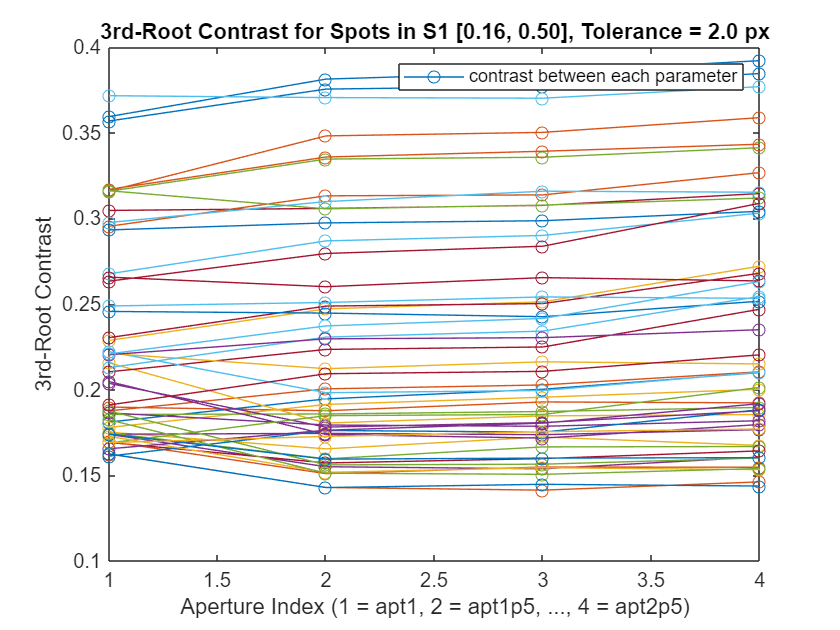



%% 6) Plot how the *third-root* contrast changes across all 7 files
figure;
plot(matchedTransformedValid', '-o');  % Chaque ligne = un spot ; colonnes = S1 → S7
xlabel('Aperture Index (1 = apt1, 2 = apt1p5, ..., 4 = apt2p5)');
ylabel('3rd-Root Contrast');
title(sprintf('3rd-Root Contrast for Spots in S1 [%.2f, %.2f], Tolerance = %.1f px', ...
    valMin, valMax, tol));

% Optionnel : ajouter la légende
legend('contrast between each parameter');


% Moyenne des contrastes ³√ pour chaque paramètre (S2 à S7)
avgContrast = mean(matchedTransformedValid(:, 2:end), 1);

% Affichage de la meilleure valeur
[maxVal, bestIdx] = max(avgContrast);
fprintf('Le meilleur contraste moyen est obtenu pour S%d (paramètre %d), avec %.4f\n', ...
    bestIdx+1, bestIdx+1, maxVal);

Le meilleur contraste moyen est obtenu pour S4 (paramètre 4), avec 0.2348


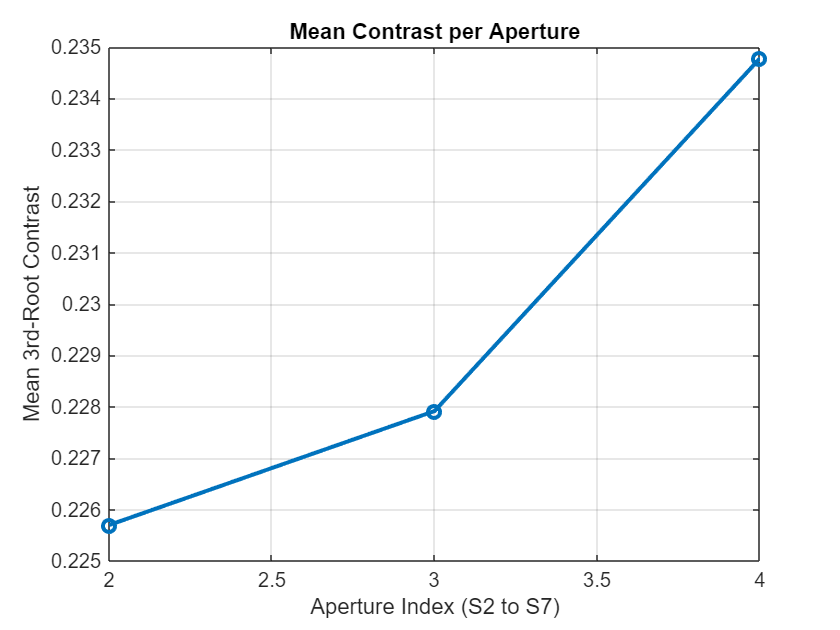


% Optionnel : plot pour visualiser les moyennes
figure;
plot(2:4, avgContrast, '-o', 'LineWidth', 2);
xlabel('Aperture Index (S2 to S7)');
ylabel('Mean 3rd-Root Contrast');
title('Mean Contrast per Aperture');
grid on;

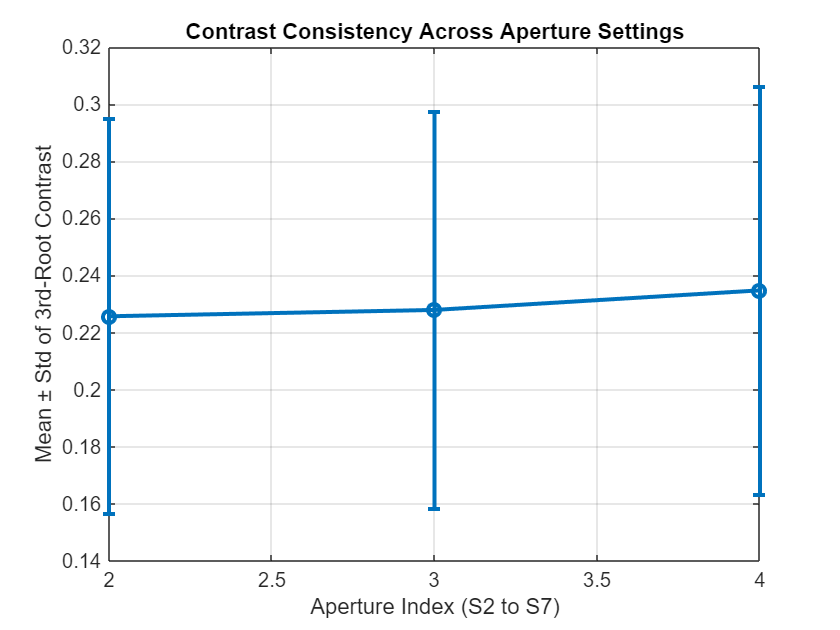


avgContrast = mean(matchedTransformedValid(:, 2:end), 1);
stdContrast = std(matchedTransformedValid(:, 2:end), 0, 1);

figure;
errorbar(2:4, avgContrast, stdContrast, '-o', 'LineWidth', 2);
xlabel('Aperture Index (S2 to S7)');
ylabel('Mean ± Std of 3rd-Root Contrast');
title('Contrast Consistency Across Aperture Settings');
grid on;